# Trabalho Cálculo Numérico (CLCO5A)

#### Alunos: Guilerme Alves Silva (a2461633), Murilo Fontana Muniz (a2478498), Rafael Ribas de Lima (a2461650).

## Problema 8:

    Se um capacitor incialmente não tem carga, a tensão através dele como uma função do tempo pode ser calculada por


$$V\left(t\right)=\frac{1}{C}\int_0^t i\left(t\right)\;\textrm{dt}$$


Se $C={10}^{-5} \;F$, use os seguitnes dados de corrente para desenvolver um gráfico da tensão em função do tempo:

Para calcular V(0,2) faça a Regra 1/3 de Simpson repetida com 2 subdivisões.

Para calcular V(0,4) faça a Regra 1/3 de Simpson repetida com 4 subdivisões.

Para calcular V(0,6) faça a Regra dos Trapézios repetida com 6 subdivisões.

Para calcular V(0,8) faça a Regra 1/3 de Simpson repetida com 2 subdivisões.

Para calcular V(1,0) faça a Regra dos Trapézios repetida com 5 subdivisões.

Para calcular V(1,2) faça a Regra 1/3 de Simpson repetida com 6 subdivisões.

% Definição dos dados
t = [0 0.2 0.4 0.6 0.8 1 1.2]; % tempo em segundos
i = [0.2 0.3683 0.3819 0.2282 0.0486 0.0082 0.1441]; % corrente em mA
C = 10^(-5); % Capacitância em Farads

% Função para calcular a integral pela Regra dos Trapézios Repetida
function result = trapezoidal_rule_repeated(x, y)
    n = length(x);
    h = (x(end) - x(1)) / (n - 1);
    result = h * (0.5 * y(1) + sum(y(2:end-1)) + 0.5 * y(end));
end

% Função para calcular a integral pela Regra de Simpson 1/3 Repetida
function result = simpson_rule_repeated(x, y)
    n = length(x);
    if mod(n-1, 2) ~= 0
        error('Número de subdivisões deve ser par para a Regra de Simpson 1/3');
    end
    h = (x(end) - x(1)) / (n - 1);
    result = y(1) + y(end);
    for k = 2:2:n-1
        result = result + 4 * y(k);
    end
    for k = 3:2:n-2
        result = result + 2 * y(k);
    end
    result = result * h / 3;
end

% Função auxiliar para calcular a integral com subdivisões corretas
function result = calculate_voltage(t, i, method, subdivisions)
    x = linspace(t(1), t(end), subdivisions + 1);
    y = interp1(t, i, x, 'linear');
    if strcmp(method, 'simpson')
        result = simpson_rule_repeated(x, y);
    elseif strcmp(method, 'trapezoidal')
        result = trapezoidal_rule_repeated(x, y);
    else
        error('Método desconhecido');
    end
end

% Cálculo das tensões nos tempos especificados
V_0_2 = calculate_voltage(t(1:2), i(1:2), 'simpson', 2) / C;
V_0_4 = calculate_voltage(t(1:3), i(1:3), 'simpson', 4) / C;
V_0_6 = calculate_voltage(t(1:4), i(1:4), 'trapezoidal', 6) / C;
V_0_8 = calculate_voltage(t(1:5), i(1:5), 'simpson', 2) / C;
V_1_0 = calculate_voltage(t(1:6), i(1:6), 'trapezoidal', 5) / C;
V_1_2 = calculate_voltage(t(1:7), i(1:7), 'simpson', 6) / C;

% Exibir resultados
fprintf('V(0.2) = %.4f V\n', V_0_2);

V(0.2) = 5683.0000 V


fprintf('V(0.4) = %.4f V\n', V_0_4);

V(0.4) = 13185.0000 V


fprintf('V(0.6) = %.4f V\n', V_0_6);

V(0.6) = 19286.0000 V


fprintf('V(0.8) = %.4f V\n', V_0_8);

V(0.8) = 23682.6667 V


fprintf('V(1.0) = %.4f V\n', V_1_0);

V(1.0) = 22622.0000 V


fprintf('V(1.2) = %.4f V\n', V_1_2);

V(1.2) = 24159.3333 V


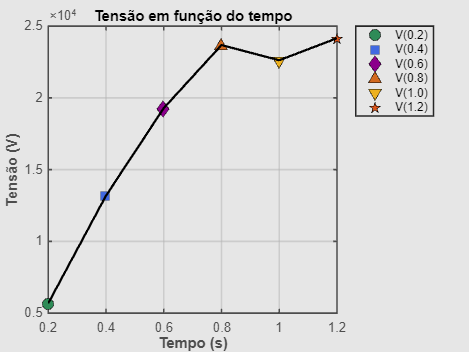


% Resultados das tensões em vetor para plotar
V = [V_0_2, V_0_4, V_0_6, V_0_8, V_1_0, V_1_2];
t_plot = [0.2, 0.4, 0.6, 0.8, 1.0, 1.2];

% Cores modernas e estilização
colors = [0.180, 0.545, 0.341; % Verde escuro
          0.255, 0.412, 0.882; % Azul médio
          0.545, 0.000, 0.545; % Roxo
          0.824, 0.412, 0.118; % Laranja
          0.929, 0.694, 0.125; % Amarelo
          0.850, 0.325, 0.098];% Vermelho

markers = {'o', 's', 'd', '^', 'v', 'p'};

% Configurando o fundo e fontes especiais
figure('Color', [0.9 0.9 0.9]); % Cor de fundo cinza claro
hold on;

% Adicionando os pontos com marcadores coloridos
for k = 1:length(t_plot)
    plot(t_plot(k), V(k), markers{k}, 'MarkerSize', 10, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', colors(k, :));
end
plot(t_plot, V, 'LineWidth', 2, 'Color', [0 0 0]);

% Configurando a aparência do gráfico
xlabel('Tempo (s)', 'FontSize', 14, 'FontWeight', 'bold', 'FontName', 'Arial');
ylabel('Tensão (V)', 'FontSize', 14, 'FontWeight', 'bold', 'FontName', 'Arial');
title('Tensão em função do tempo', 'FontSize', 16, 'FontWeight', 'bold', 'FontName', 'Arial');
grid on;
box on;
set(gca, 'FontSize', 12, 'LineWidth', 1.5, 'GridColor', [0.7 0.7 0.7], 'GridAlpha', 0.5, 'Box', 'on', 'XColor', [0.3 0.3 0.3], 'YColor', [0.3 0.3 0.3], 'Color', [0.9 0.9 0.9]);

% Adicionando legenda
legend({'V(0.2)', 'V(0.4)', 'V(0.6)', 'V(0.8)', 'V(1.0)', 'V(1.2)'}, 'Location', 'bestoutside', 'FontName', 'Arial');
hold off;